# **Figure 2**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

clear
clc
addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions') ) % Add path of the "Functions" folder.

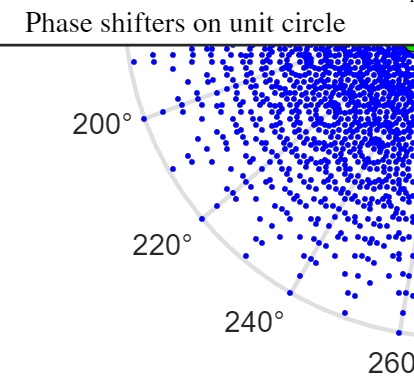

N=18;
[Setb,Sb,Set,~]=GenUniqueSet(N);
S=exp(1j*2*pi*(0:N-1)/N);

Fig=figure;
polarplot(angle(Set),abs(Set),'b.')
hold on
polarplot(angle(S),abs(S),'o','Markersize',6,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',[0 .9 0])
% Phi=0:.1:2*pi;
% polarplot(Phi,ones(length(Phi),1),'Color',[17 17 17]/255)

ax=gca;
ax.RTick = [];
% ax.RTickLabel =[1 5.1258 6];
rlim([0 max(abs(Setb))])
ax.ThetaTick = 0:360/N:360;
% ax.ThetaAxis.Color = 'r';
ax.ThetaColor=[.15 .15 .15]; 
ax.RColor=[.15 .15 .15];
ax.LineWidth = 1.5;

Legend2='Phase shifters on unit circle';
Legend1=['Elements of the feasible set for $N_{\mathrm{ps}}=$',num2str(N)];
lgd=legend(Legend1,Legend2);
lgd.Location= 'northwest'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;

ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ ax.TightInset(4)+ ax.Position(4))+1];